# **IO682 - ARINC 429 Loopback**

This example shows you how to perform a loopback test with the IO682 ARINC 429 I/O module, in order to verify the basic communication over the Transmit and Receive channels.

The IO682 I/O module is a multi-channel ARINC 429 interface module supporting up to 16 receive and transmit channels.

This example demonstrates the use of scheduled messages on channel 1 and channel 2, as well as standard communication on the same channels.

The Simulink model features the [IO682 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io682_setup_v4), [IO682 Receive](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io682_receive_v4), [IO682 Send](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io682_send_v4), [ARINC 429 Encode](https://www.speedgoat.com/help/slrt/page/io_main/refentry_arinc429_encode_v4), [ARINC 429 Decode](https://www.speedgoat.com/help/slrt/page/io_main/refentry_arinc429_decode_v4), [ARINC 429 Pack](https://www.speedgoat.com/help/slrt/page/io_main/refentry_arinc429_pack), [ARINC 429 Unpack](https://www.speedgoat.com/help/slrt/page/io_main/refentry_arinc429_unpack) and [Update Scheduled Message](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io682_update_scheduled_messages_v4) blocks.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO682 I/O module installed

- Connector cable from the I/O module to the terminal board

- 68-pin terminal board with jumper wires

### Test Setup

In this example, channel 1 and channel 2 are used together. You must therefore connect the pins on the terminal board where the Transmit and Receive channels are located.

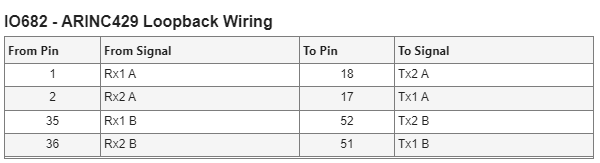

The full pin mapping of the IO682 can be found here: [IO682 pin mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io682_pin_mapping)

## Initialize and Open the Simulink Model

 
% Open Simulink model
modelName = 'sgMdl_IO682_ARINC429Loopback';
open_system(modelName);

### Model Description

Please note that, by default, this Simulink model is configured for use with an IO682-8-8. To change to another variant, change the **IO682 Variant** in all the serial blocks.

In the model, the message with label 101 is a scheduled message, configured in the Setup block for channel 1. The message with label 202 is not scheduled and is therefore treated with lower priority than the scheduled message, should both these messages arrive at the same time in the output buffer**.** 

The sine wave is BNR-encoded together with the label specified by the [ARINC 429 Encode](https://www.speedgoat.com/help/slrt/page/io_main/refentry_arinc429_encode_v4) block, and the [ARINC 429 Decode](https://www.speedgoat.com/help/slrt/page/io_main/refentry_arinc429_decode_v4) block is used to decode the signal from the ARINC 429 message on the receiving side. This ensures a convenient way of accessing the data and timestamp of the ARINC 429 message received. 

On channel 2, the message is encoded with the [ARINC 429 Pack](https://www.speedgoat.com/help/slrt/page/io_main/refentry_arinc429_pack) block. Besides the BNR-encoded sine wave, a status flag is included in the ARINC 429 message with label 202. The message then gets decoded with the  [ARINC 429 Unpack](https://www.speedgoat.com/help/slrt/page/io_main/refentry_arinc429_unpack) block. The pack and unpack blocks allow working with separate signals when your message contains mixed data types. 

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName,'SimulationMode',   'external')   % put model into External Mode
set_param(modelName,'SimulationCommand','connect')    % connect with External Mode

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Check the Results

To check if the loopback is working as expected, open the Simulink scopes connected to the Receive blocks. A sine wave must be displayed on each scope. Additionally on the second scope, the status bit and the SSM signal must be displayed as shown below:

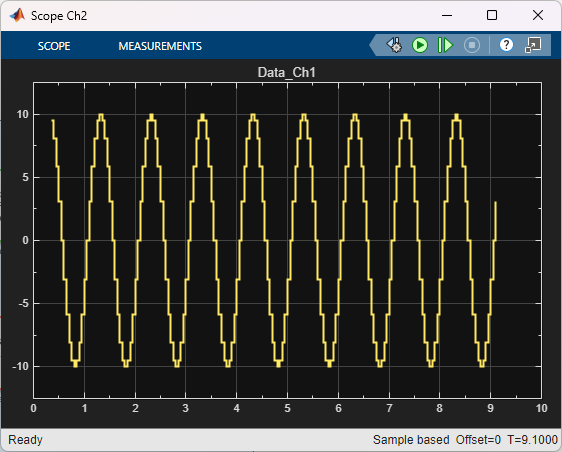

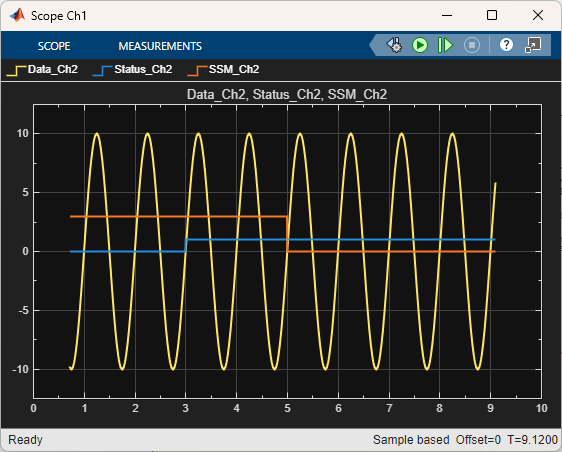

## Additional References

- [IO682 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io682)